# P5. Estimación de estado y frenado de emergencia

Sistemas de Control de Vehículos

Grado en Ingeniería Electrónica, Robótica y Mecátronica

Universidad de Málaga

Creado por: David Rodríguez Martínez

Última actualización: 19 Octubre 2026

### Introducción y objetivos

Esta es la práctica más completa. Por primera vez integraremos los cinco módulos de nuestro gemelo digital:` pasoDinamico` (desarrollado en P1+P2), `controlLongitudinal` (desarrollado en P1-P3), `controlLateral` (desarrollado en P4), `estimadorEstado` y `frenadoEmergencia`. Esta práctica se centra en el desarrollo de estos dos últimos. El ciclo de simulacións seguirá siempre el siguiente orden:

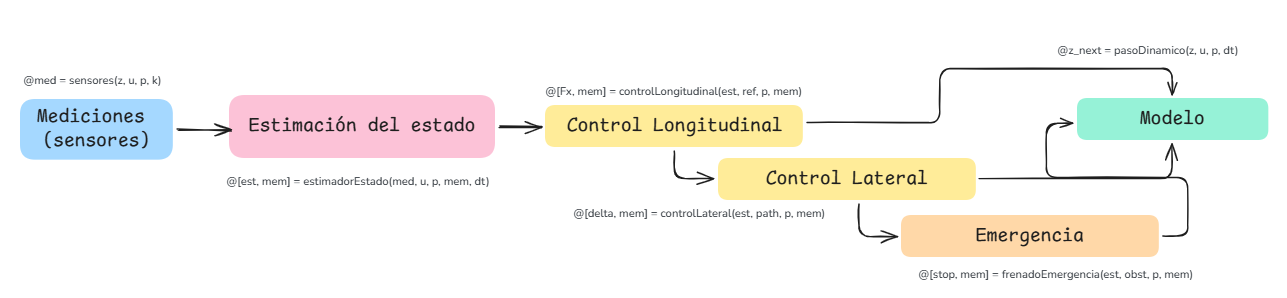

Hasta ahora nuestros controladores recibian siempre el estado real del vehículo. En la realidad el GPS nos darán una posición afectada de ruido y a baja frecuencia, la IMU nos dará ruido en la aceleracion y velocidad de giro y al integrar estos valores, la estimación derivará debido a la propagación del error de estimación en el tiempo. 

Para ello vamos a implementar un filtro de Kalman extendio (EKF) que combine y filtre ambas mediciones. 

*💡 Recordatorio de teoría: ¿Qué es el filtro de Kalman?*

* Es un algoritmo matemático recursivo (i.e., únicamente requiere el último estado estimado y no el histórico) desarrollado por Rudolf E. Kalman en 1960 para estimar el estado oculto o no medible de un sistema dinámico a partir de una serie de mediciones ruidosas e inciertas a lo largo del tiempo. El algoritmo trabaja de forma continua mediante un ciclo de dos pasos principales:*

- ***Predicción (a priori):**** Utiliza un modelo matemático del sistema para calcular una estimación del estado actual basándose en el estado anterior. *

- ***Actualización (a posteriori):**** Recoge las nuevas mediciones de los sensores (que suelen tener ruido o errores) y las combina con la predicción teórica. A través de la ****ganancia de Kalman****, el algoritmo decide cuánto confiar en el modelo frente a los sensores para minimizar el error de la estimación.*

*El filtro de Kalman clásico (KF) nos da una estimación del estado y además su incertidumbre asociada (matriz de covarianza). ****Su variante extendida (filtro de Kalman extendido o EFK) nos permite utilizar este estimador de estado con sistemas no lineales****. *

🧠 El estado del vehículo en linea recta a velocidad constante puede estimarse mediante un KF clásico, pero en el momento en que tomemos una curva o cambie el ángulo de inclinación de la calzada, se introducen no linealidades en el modelo. El EKF toma esas no linealidades y las linealiza en cada paso a través de la **matriz jacobiana, **pudiendo aplicar la lógica del filtro clásico en cada paso**.**

Por último, implementaremos también un frenado autonomo de emergencia basado en TTC (*time to collision*)

El estimador que programemos tendrá la siguiente estructura

% [est, mem] = estimadorEstado(med, u, p, mem, dt)

- `med:` medición de sensores (e.g., `med.gyro`: medición de la velocidad de giro por al IMU o `med.gps_X`: medición de la posición global en X del GPS)

- `est`: estado estimado del vehículo `[est.X, est.Y, est.psi, est.vx, est.vy, est.r]`

Y el controlador de frenada de emergencia:

% [stop, mem] = frenadoEmergencia(est, obst, p, mem)

- `obst:` la posición del obstáculo a evitar.

Al terminar esta práctica deberás ser capaz de:

- Entender por qué el control debe ser robusto frente a estimaciones ruidosas e impletas (GPS, IMU, etc.)

- Implementar un EKF que fusione GPS + IMU para estimar el estado del vehículo en cada instante de tiempo, y alimentar con esa estimación a los controladores de la dinámica longitudinal y lateral.

- Implementar un frenado de emergencia por TTC (*time to collision*).

- Por primera vez, ver el simulador de nuestro vehículo en su totalidad. 

#### Qué vas a implementar

A) Un filto de Kalman extendido dentro de `estimadorEstado.`

B) Un TTC, incluyendo el calculo de la distancia hasta el obstáculo y la condición de disparo en `frenadoEmergencia. `

### Parametros del vehículo, controlador y de la calzada

p = struct(); % definición explicita (no es necesaria)

p.m    = 230;      % masa [kg]                              
p.g    = 9.81;     % gravedad [m/s^2]
p.rho  = 1.225;    % densidad del aire [kg/m^3]
p.Cd   = 1.0;      % coef. aerodinámico                       
p.Af   = 1.1;      % área frontal [m^2]                        
p.fr  = 0.022;    % coef. de resistencia a la rodadura       
p.Fx_drive_max = 2500;   % fuerza motriz máxima [N]           
p.Fx_brake_max = 5000;   % fuerza de frenado máxima [N]       
p.theta        = 0;      % inclinación de la calzada [rad]

% adherencia por eje
p.mu_t = 1.5; 
p.mu_d = 0.95*p.mu_t; 

% dinámica lateral del vehículo
p.ld = 0.765; % CG-eje delantero [m] % regla del FS drive es que la batalla tiene que ser superior a 1.525 m
p.lt = 0.765; % CG-eje trasero [m]
p.Iz = 130; % inercia en guiñada [kg·m^2]
p.Cad = 35000; % rigidez de deriva delantera [N/rad]
p.Cat = 50000; % rigidez de deriva trasera [N/rad]

% ley ACC
p.d0  = 6;       % distancia mínima parado [m]
p.h   = 1.5;     % tiempo de cabecera [s]                   
p.Kv  = 1.5;     % ganancia modo velocidad [1/s]            
p.Kg  = 0.4;     % ganancia modo distancia [1/s^2*m]    
p.Kd  = 1.0;     % ganancia sobre velocidad relativa [1/s]
p.jerk_max = 30; % límite de variación de aceleración (sobreaceleración, sacudidas) [m/s^3]

% control de velocidad sencillo
p.Kv_v = 800;
p.Ki_v = 200;




### Modelo del vehículo

Dado el **estado actual del vehículo, fuerza tractiva aplicada, y el ángulo de giro del volante** deberemos calcular dónde se encuentra el vehículo en el siguiente paso temporal:

function z_next = pasoDinamico(z, u, p, dt)
    Fx = u(1);
    delta = u(2);
    X = z(1); Y =z(2); psi = z(3);
    vx = z(4); vy = z(5); r = z(6);
    L = p.ld + p.lt;
    vx_c = max(vx, 1.0); % velocidad corregida para no dividir por 0 (angulos de deriva)
    
    % ángulos de deriva y fuerzas laterales
    alpha_d = delta - (vy + p.ld*r)/vx_c;
    alpha_t = - (vy - p.lt*r)/vx_c;
    Fyd = p.Cad*alpha_d; % modelo del neumático lineal 
    Fyt = p.Cat*alpha_t; % modelo del neumático lineal

    % Límite de adherencia (presupuesto mu·Fz por eje)
    Fzd = p.m*p.g*p.lt/L;  
    Fzt = p.m*p.g*p.ld/L;
    % Saturación eje delantero 
    Fyd = max(min(Fyd, p.mu_d*Fzd), -p.mu_d*Fzd); 
    % Saturación eje trasero  
    Fyt = max(min(Fyt, p.mu_t*Fzt), -p.mu_t*Fzt);
    % Agarre longitudinal
    Fx_max = p.mu_d*Fzd + p.mu_t*Fzt;
    Fx = max(min(Fx, Fx_max), - Fx_max);

    % Dinámica longitudinal 
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2;      % resitencia aerodinámica
    Rr  = p.fr*p.m*p.g*cos(p.theta);    % rodadura (opuesta al avance)
    Rg = p.m*p.g*sin(p.theta);          % gravedad (0 en E1)  
    
    % Ecuaciones del movimiento (chasis, CG)
    ax_l    = (Fx - Ra - sign(vx)*Rr- Rg) / p.m; % ecuación del movimiento de P1
    ax = ax_l + vy*r; % P1 + acoplamiento (componente centripeta, cambio en la dirección del vector velocidad por el giro)
    ay = (Fyd + Fyt)/p.m - vx*r;
    dr  = (p.ld*Fyd - p.lt*Fyt)/p.Iz;

    % Integración y cinemática global
    vx_next  = max(vx + ax*dt, 0);
    vy_next  = vy + ay*dt;
    r_next   = r  + dr*dt;
    X_next   = X + (vx*cos(psi) - vy*sin(psi))*dt;
    Y_next   = Y + (vx*sin(psi) + vy*cos(psi))*dt;
    psi_next = psi + r*dt;
    z_next = [X_next; Y_next; psi_next; vx_next; vy_next; r_next];
end

### Controlador de velocidad 

Vamos a reutilizar los controladores ya definidos: `controlLongitudinal` definido en P3 (ACC) y el `controlLateral` definido en P4 (Pure Pursuit). Vamos a complementar estos con un controlador para la frenada de emergencia (`frenadoEmergencia`)

% LONGITUDINAL
function [Fx, mem] = controlLongitudinal(est, ref, p, mem)

end

% LATERAL
function [delta, mem] = controlLateral(est, path, p, mem)

end

% FRENADA DE EMERGENCIA
function [stop, mem] = frenadoEmergencia(est, obst, p, mem)

end

### Estimador de estado

Implementación de un EKF que fusione GPS (posición global) + IMU (aceleración y velocidad de giro)

function [est, mem] = estimadorEstado(med, u, p, mem, dt)

end

En nuestro caso la medición de los sensores la vamos a simular: 

function med = sensores(z, u, p, k)

end 

### Geometría del circuito de pruebas

Vamos a simular la prueba de Autocross: una única vuelta a un circuito

% Misión del ADAS


function [centro, cono_izq, cono_der] = generarPista(ancho)
% Pista de Autocross cerrada (misma que en P4)
    N = 240;  s = linspace(0, 2*pi, N+1)';  s(end) = [];
    a = 40; b = 26;
    xc = a*cos(s);  yc = b*sin(s) + 6*sin(2*s);
    centro = [xc, yc];
    dx = gradient(xc);  dy = gradient(yc);
    Ln = hypot(dx,dy);  nx = -dy./Ln;  ny = dx./Ln;
    cono_izq = [xc + (ancho/2)*nx, yc + (ancho/2)*ny];
    cono_der = [xc - (ancho/2)*nx, yc - (ancho/2)*ny];
end

### Simulación

dt = p.dt;
% Estado inicial: en el primer punto de la pista, orientado hacia el segundo
ir0 = atan2(centro(2,2)-centro(1,2), centro(2,1)-centro(1,1));
z0 = [centro(1,1); centro(1,2); dir0; p.v_set*0.5; 0; 0]; % estado inicial


### Resultados 